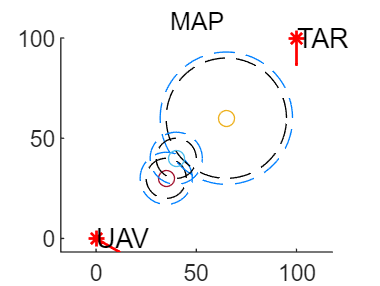

clear all
%% 定义函数输入
Start_Point = [0,0,-pi/6];
End_Point = [100,100,-pi/2];%[x,y,角度]
r=15;%最小转弯半径
Stepsize=0.01;%路径的生成间隔

sure=3;%保证安全的预留距离
% R=10+sure;
obs=[35,30,10+sure;
     65,60,30+sure;
     40,40,10+sure];%[x,y,障碍物的半径R]

figure(1)
Draw_map(Start_Point,End_Point,obs,sure);%绘制地图

hold off

%A*算法开始

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%初始节点
open={};
close={};
open_f=[];

%%节点[点的位置(出发点)，方向(1个)，f,g，无path]

node.point=Start_Point(1:2);
node.vtheta=Start_Point(3);
node.g=0;
node.f=node.g+obtain_h(node.point,End_Point(1:2));




% =[Start_Point(1:2),Start_Point(3),0+obtain_h(Start_Point(1:2),End_Point(1:2)),0];
open{end+1}=node;
open_f=[open_f,node.f];



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%产生初始路径
figure(2)
Draw_map(Start_Point,End_Point,obs,sure);

[param_all_start,param_best_start] = Dubins_no_obs(Start_Point, End_Point,r,r,Stepsize);

%判断所有的初始路径是否不碰撞
flag_all=zeros(1,length(obs(:,1)));%%障碍物m个=>m列
for i=1:4
    flag_safe=if_safe(param_all_start(i).path,obs,1,3);
    flag_all(i,:)=flag_safe;
end

% flag_all=obtian_flag_safe(param_all_start,obs);



%%如果有安全的
path_safe_flag=[];
for i = 1:length(flag_all(:,1))
    if all(flag_all(i, :) == 1)
        path_safe_flag=[path_safe_flag,i];%某行全1=>该路径安全
    end
end
%%选择安全中最短的
if ~isempty(path_safe_flag)
    min_path=inf;
    for i=1:length(path_safe_flag)
        if param_all_start(path_safe_flag(i)).Length<min_path
            min_path=param_all_start(path_safe_flag(i)).Length;
            flag_min=i;
        end
    end
    disp('Find Goal!!');
    Draw_path(param_all_start(path_safe_flag(flag_min)),sure,1,3)
end
   



%%选出碰撞的障碍物n个（及其路径）
[path_num, obs_num] = find(flag_all == 0);%%第pah_num行，第obs_num列为0
[obs_to_avoid, ~, ~] = unique(obs_num);
%%生成避障路线n(转弯半径只有1种)*4===>n=0,则选择最优直达
%%初始节点[点的位置(起点)，方向，f,g,path]
for i=1:length(obs_to_avoid)
    [param_all{i},param_best{i}] = Dubins_obs(Start_Point,End_Point,obs(obs_to_avoid(i),1:2),r,r,obs(obs_to_avoid(i),3),Stepsize);
%     [param_all{2,i},param_best{2,i}] = Dubins_obs(Start_Point,End_Point,obs(obs_to_avoid(i),1:2),r,r,obs(obs_to_avoid(i),3),Stepsize);
end
%%param_all=>k列=K个障碍物==>每一个cell是一个1*4（4种路径）的结构体


%%检查避障路线的from_path=1,to_path=2是否碰撞
% %（从当前节点到下一节点）
flag_all=zeros(1,length(obs(:,1)));
for j=1:length(obs_to_avoid)%%针对每个障碍物
    for i=1:4
        flag_safe=if_safe(param_all{j}(i).path,obs,1,2);
        flag_all((i+4*(j-1)),:)=flag_safe;
    end
end

path_safe_flag=[];
for i = 1:length(flag_all(:,1))
    if all(flag_all(i, :) == 1)
        path_safe_flag=[path_safe_flag,i];%某行全1=>该路径安全
    end
end
%(路径数=需要躲避障碍物数*4)*障碍物数



%%选择不碰撞的路径，g=到起点的距离=path.1+path.2,h=直线距离？
%%节点[点的位置(2个=出发圆+障碍圆切入)，方向(1个)，f,g,path(2个=弧度+直线)]
for i=1:length(path_safe_flag)
    param=param_all{ceil(path_safe_flag(i)/4)}(path_safe_flag(i)-4*(ceil(path_safe_flag(i)/4)-1));
    %%索引路径参数第几（初始半径）行第几（躲避障碍圆）个，具体第几个路径
    node.point=param.point(:,2:3);
    node.vtheta=param.vtheta(2);
    node.g=sum(param.length(1:2));
    node.f=node.g+obtain_h(node.point(:,2)',End_Point);
    node.path{1}=param.path{1};
    node.path{2}=param.path{2};
    node.R=param.R;
    node.obs=param.center(:,2);
    open_f=[open_f,node.f];
    open{end+1}=node;
end

%%选择最短节点
% min_f=inf;
% for i=1:length(open)
%     if open{i}.f<min_f
%         min_f=opn{i}.f
%         flag_min=i;
%     end
% end

flag_min=find(open_f==min(open_f));

%%移除open，加入close
% open{flag_min}
close{end+1}=open{flag_min};
open{flag_min}={};
open_f(flag_min)=[];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%循环开始
%%生成无碰撞路径2(半径不同)*4

[param_all_obs{1},param_best_obs{1}] = Dubins_no_obs([close{end}.point(:,2)',close{end}.vtheta], End_Point,r,r,Stepsize);
[param_all_obs{2},param_best_obs{2}] = Dubins_no_obs([close{end}.point(:,2)',close{end}.vtheta], End_Point,close{end}.R,r,Stepsize);
%%判断所有的初始路径是否不碰撞(和自己碰撞直接排除)=>直接生成
flag_all=[];
for j=1:2%%针对两个半径
    for i=1:4%%针对每个路段
        flag_safe=if_safe(param_all_obs{j}(i).path,obs,1,2);
        flag_all(i+4*(j-1),:)=flag_safe;
    end
end


%%如果有安全的
path_safe_flag=[];
for i = 1:length(flag_all(:,1))
    if all(flag_all(i, :) == 1)
        path_safe_flag=[path_safe_flag,i];%某行全1=>该路径安全
    end
end
%%选择安全中最短的
if ~isempty(path_safe_flag)
    min_path=inf;
    for i=1:length(path_safe_flag)
        if param_all_start(path_safe_flag(i)).Length<min_path
            min_path=param_all_start(path_safe_flag(i)).Length;
            flag_min=i;
        end
    end
    disp('Find Goal!!');
    Draw_path(param_all_start(path_safe_flag(flag_min)),sure,1,3)
end
   

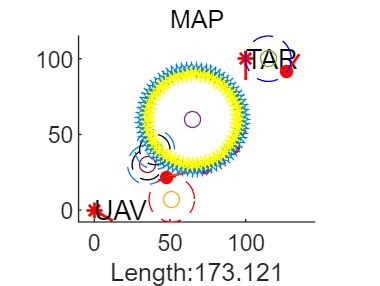

[path_num, obs_num] = find(flag_all == 0);
[obs_to_avoid, ~, ~] = unique(obs_num);

%%选出碰撞的障碍物(排除和自己的转弯圆碰撞)n个（及其路径）
for i=1:length(obs_to_avoid)
    if isequal(obs(i,1:2),close{end}.obs')
        flag_all(:,i)=1;
    end
end

[path_num, obs_num] = find(flag_all == 0);
[obs_to_avoid, ~, ~] = unique(obs_num);

%%%%%%%%%%%%%%%%%%确定具体的躲避障碍

%%生成避障路线n(转弯半径2种)*4===>n=0,则选择最优直达
%%初始节点[点的位置(起点)，方向，f,g,path]
param_all={};
for i=1:length(obs_to_avoid)
    [param_all{1,i},param_best{1,i}] = Dubins_obs([close{end}.point(:,2)',close{end}.vtheta],End_Point,obs(obs_to_avoid(i),1:2),r,r,obs(obs_to_avoid(i),3),Stepsize);
    [param_all{2,i},param_best{2,i}] = Dubins_obs([close{end}.point(:,2)',close{end}.vtheta],End_Point,obs(obs_to_avoid(i),1:2),close{end}.R,r,obs(obs_to_avoid(i),3),Stepsize);
end

flag_all_r=[];
flag_all_R=[];
for j=1:length(obs_to_avoid)%%针对每个障碍物
    for i=1:length(param_all{1,j})%%针对每个路段
        flag_safe_r=if_safe(param_all{1,j}(i).path,obs,1,2);
        flag_all_r(i+4*(length(obs_to_avoid)-1),:)=flag_safe_r;
        flag_safe_R=if_safe(param_all{2,j}(i).path,obs,1,2);
        flag_all_R(i+4*(length(obs_to_avoid)-1),:)=flag_safe_R;
    end
end
%%如果有安全的
path_safe_flag_r=[];flag_min_r=0;
for i = 1:length(flag_all_r(:,1))
    if all(flag_all_r(i, :) == 1)
        path_safe_flag_r=[path_safe_flag_r,i];%某行全1=>该路径安全
    end
end
path_safe_flag_R=[];flag_min_R=0;
for i = 1:length(flag_all_R(:,1))
    if all(flag_all_R(i, :) == 1)
        path_safe_flag_R=[path_safe_flag_R,i];%某行全1=>该路径安全
    end
end
%%选择安全中最短的
if ~isempty(path_safe_flag_r)
    min_path_r=inf;
    for i=1:length(path_safe_flag_r)
        if param_all(path_safe_flag_r(i)).Length<min_path_r
            min_path_r=param_all(path_safe_flag_r(i)).Length;
            flag_min_r=i;
        end
    end
end

if ~isempty(path_safe_flag_R)
    min_path_R=inf;
    for i=1:length(path_safe_flag_R)
        if param_all(path_safe_flag_r(i)).Length<min_path_R
            min_path_R=param_all(path_safe_flag_r(i)).Length;
            flag_min_R=i;
        end
    end
end

% 判断条件并选择
if flag_min_r~=0 && flag_min_R~=0
    disp('Find Goal!!');
    [minValue, index] = min([min_path_R,min_path_r]);
    if index==1   
        Draw_path(param_all(path_safe_flag_R(flag_min_R)),sure,1,3);
    else 
        Draw_path(param_all(path_safe_flag_r(flag_min_r)),sure,1,3);
    end

elseif flag_min_r~=0
    min_path=min_path_r;
    Draw_path(param_all(path_safe_flag_r(flag_min_r)),sure,1,3);
elseif flag_min_R~=0
    min_path=min_path_R;
    Draw_path(param_all(path_safe_flag_R(flag_min_R)),sure,1,3);
end



%%选择不碰撞的路径，g=到起点的距离=path.1+path.2,h=直线距离？
%%节点[点的位置(2个=出发圆+障碍圆切入)，方向(1个)，f,g,path(2个=弧度+直线)]
for i=1:length(path_safe_flag_r)
    param=param_all{ceil(path_safe_flag_r(i)/4)}(path_safe_flag_r(i)-4*(ceil(path_safe_flag_r(i)/4)-1));
    %%索引路径参数第几（初始半径）行第几（躲避障碍圆）个，具体第几个路径
    node.point=param.point(:,2:3);
    node.vtheta=param.vtheta(2);
    node.g=sum(param.length(1:2));
    node.f=node.g+obtain_h(node.point(:,2)',End_Point);
    node.path{1}=param.path{1};
    node.path{2}=param.path{2};
    node.R=param.R;
    node.obs=param.center(:,2);
    open_f=[open_f,node.f];
    open{end+1}=node;
end

for i=1:length(path_safe_flag_R)
    param=param_all{ceil(path_safe_flag_R(i)/4)}(path_safe_flag_R(i)-4*(ceil(path_safe_flag_R(i)/4)-1));
    %%索引路径参数第几（初始半径）行第几（躲避障碍圆）个，具体第几个路径
    node.point=param.point(:,2:3);
    node.vtheta=param.vtheta(2);
    node.g=sum(param.length(1:2));
    node.f=node.g+obtain_h(node.point(:,2)',End_Point);
    node.path{1}=param.path{1};
    node.path{2}=param.path{2};
    node.R=param.R;
    node.obs=param.center(:,2);
    open_f=[open_f,node.f];
    open{end+1}=node;
end


flag_min=find(open_f==min(open_f));

%%移除open，加入close
% open{flag_min}
close{end+1}=open{flag_min};
open{flag_min}={};
open_f(flag_min)=[];

%%%%%%%%%%%%%%%%%循环结束
Draw_path(param_best{1},sure,1,2)
hold off